## Исследование однофазного двухполупериодного управляемого выпрямителя

Цель работы: Исследование на компьютерной модели однофазного управляемого выпрямителя при работе на активно-индуктивную нагрузку с противо-э.д.с. и обратным диодом. 

### Описание виртуальной лабораторной установки

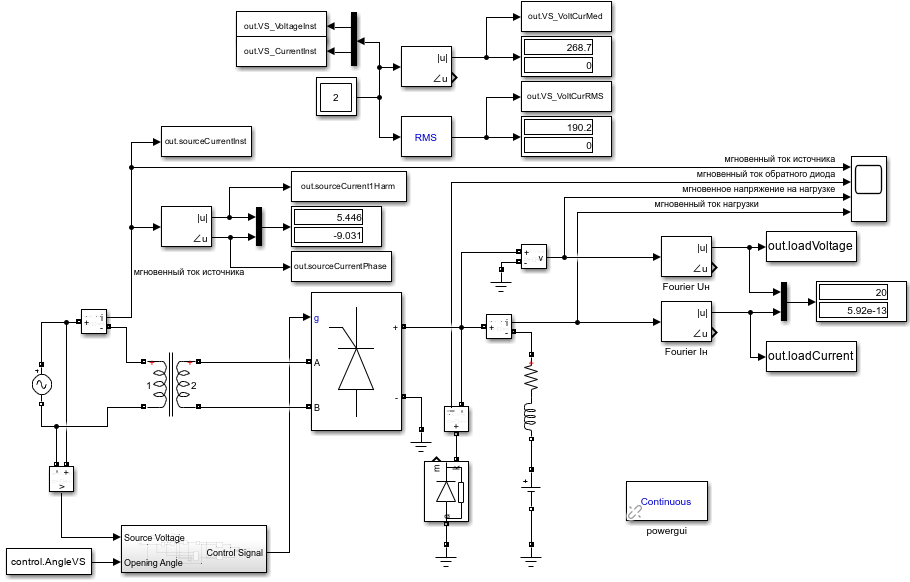

Рисунок 1 - Модель однофазного управляемого выпрямителя 

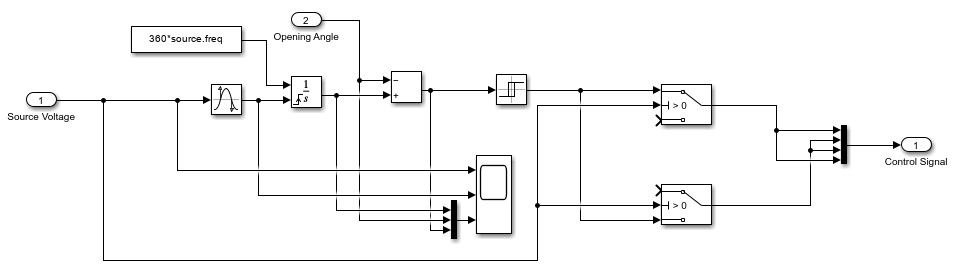

Рисунок 2 -  Модель блока управления

Параметры источника питания

source.voltage = 220;
source.voltageMag = source.voltage * sqrt(2);
source.freq = 50;

Параметры трансформатора

transparam.power = 300 * 10^3;
transparam.volt1wing = 220;
K_T = 1;
transparam.volt2wing = transparam.volt1wing * K_T;

Напряжение вторичной обмотки:

fprintf("U2 = %d В",transparam.volt2wing);

U2 = 220 В

Параметры нагрузки

load.Res = 1;
load.Ind = load.Res * 2 / source.freq;

Индуктивность нагрузки: 

fprintf("Lн = %.4g Гн", load.Ind);

Lн = 0.04 Гн

load.EMFdata = 20;

Параметры тиристоров

VS.ForwardVoltage = 1;
VS.InternalResistance = 0.001;

Данные для моделирования и подготовка массивов

StepEMF = 20;
StepAngle = 20;
EMF = 0:StepEMF:100;
AngleVS = 0:StepAngle:180;
I_n = [];
U_n = [];
I_1max = [];
Phi_1max = [];
I_VSD = [];
I_VS = [];
U_VSmax = [];
I_VSmax = [];
S_1 = [];
P_1 = [];
P_n = [];
P_T = [];
EMF_tbl = [];
Angle_tbl = [];
 

## Порядок проведения лабораторной работы

### Исследование внешних и энергетических характеристик однофазного управляемого выпрямителя при работе на активно-индуктивную нагрузку с противо-э.д.с. и обратным диодом.

Запускаем собранную схему и формируем таблицу результатов моделирования

 
for i = 1:length(AngleVS)
    control.AngleVS = AngleVS(i);
    for j = 1:length(EMF)
        load.EMF = EMF(j);
        sim("lr2.slx");
        EMF_tbl(end+1) = EMF(j);
        Angle_tbl(end+1) = AngleVS(i);
        I_n(end+1) = ans.loadCurrent(end);
        U_n(end+1) = ans.loadVoltage(end);
        I_1max(end+1) = ans.sourceCurrent1Harm(end);
        Phi_1max(end+1) = ans.sourceCurrentPhase(end);
        I_VSD(end+1) = ans.VS_VoltCurMed(end, 2);
        I_VS(end+1) = ans.VS_VoltCurRMS(end, 2);
        U_VSmax(end+1) = max(ans.VS_VoltageInst);
        I_VSmax(end+1) = max(ans.VS_CurrentInst);
        S_1(end+1) = source.voltageMag * I_1max(end) / 2;
        P_1(end+1) = S_1(end) * cosd(Phi_1max(end));
        P_n(end+1) = U_n(end) * I_n(end);
        P_T(end+1) = VS.ForwardVoltage*I_VS(end) + VS.InternalResistance*I_VSD(end)^2;
    end
end
T = table(Angle_tbl.',EMF_tbl.', I_n.',U_n.',I_1max.',Phi_1max.', I_VSD.', I_VS.', U_VSmax.', I_VSmax.', S_1.', P_1.', P_n.', P_T.');
T.Properties.VariableNames = ["alpha", "E", "Iн", "Uн", "I1max","phi1max", "I_VSD", "I_VS", "U_VDmax", "I_VDmax", "S1", "P1", "Pн", "P_T"];
T.Properties.Description = "Таблица 1 - Результаты моделирования";
disp(T.Properties.Description); disp(T);

Таблица 1 - Результаты моделирования
    alpha     E         Iн            Uн        I1max     phi1max      I_VSD          I_VS       U_VDmax    I_VDmax       S1        P1          Pн           P_T    
    _____    ___    __________    __________    ______    _______    __________    __________    _______    ________    ______    ______    __________    __________

       0       0         186.4        186.41    240.57    -2.4448        118.73        130.64    1.1915       191.55     37424     37390         34747      

### Исследование регулировочных характеристик однофазного управляемого выпрямителя при работе на активно-индуктивную нагрузку с противо-э.д.с. и обратным диодом.

Снимаем регулировочные характеристики

 
Angle_tbl2 = [];
U_n_tbl2 = [];
load.EMF = load.EMFdata;

for i = 1:length(AngleVS)
    control.AngleVS = AngleVS(i);
    sim("lr2.slx");
    U_n_tbl2(end+1) = ans.loadVoltage(end);
end

T2 = table(AngleVS.', U_n_tbl2.');
T2.Properties.VariableNames = ["alpha", "Uн"];
T2.Properties.Description = "Таблица 2 - Регулировочная характеристика";
disp(T2.Properties.Description); disp(T2);

Таблица 2 - Регулировочная характеристика
    alpha      Uн  
    _____    ______

       0     187.38
      20      182.6
      40     167.08
      60     142.55
      80     111.96
     100     79.029
     120     47.772
     140     22.303
     160     20.145
     180         20



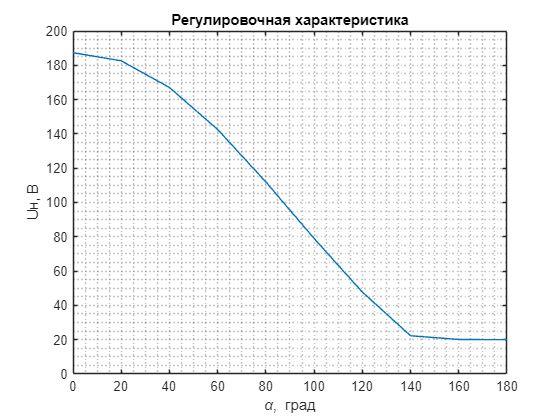

plot(AngleVS, U_n_tbl2);
xlabel("\alpha, град");
ylabel("Uн, В");
grid("minor");
title("Регулировочная характеристика");

### Исследование гармонического состава тока потребления однофазного управляемого выпрямителя.

Исследование сигналов управления выпрямителя осуществляется при одном значении угла управления

control.AngleVS = 70; %задаём угол рег.

Запускаем инструмент спектрального анализа

Исследование сигналов управления выпрямителя

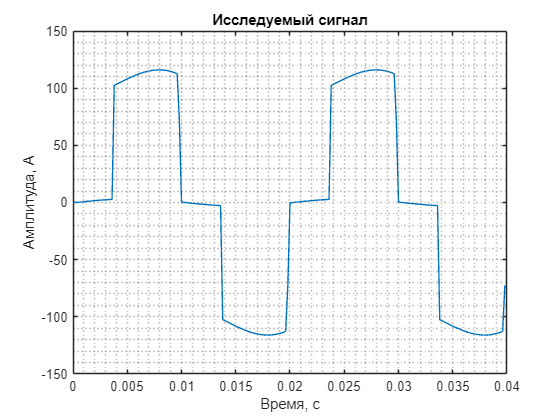

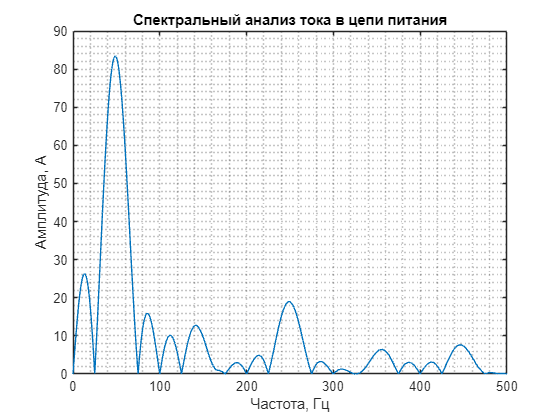

sim("lr2.slx");
currentSpectr = ans.sourceCurrentInst;
run("lr2_spectral.m");